% 数据读取（此文件用于生成分解后连杆）
clear; clc; close all force; 
Para_path = '.';
load(fullfile(Para_path, "Data_Dongjili_5tihuan_750s.mat"))
Ts = 0.001;
Tswitch = 10;  % 滞留时间
endtime = 10+250;
data.t = Data(Tswitch/Ts+1:endtime/Ts,1)-Tswitch';
data.q = Data(Tswitch/Ts+1:endtime/Ts,2:4);
data.Pa = Data(Tswitch/Ts+1:endtime/Ts,[5 6 7])*10^6;
data.Pb = Data(Tswitch/Ts+1:endtime/Ts,[8 9 10])*10^6;
clear Data;

sacle = 100;
data.t = downsample(data.t,sacle);
data.q = downsample(data.q,sacle);
data.Pa = downsample(data.Pa,sacle);
data.Pb = downsample(data.Pb,sacle);

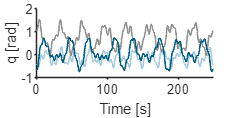

figure;
plot(data.t, data.q(:,1),'LineWidth',1,'color','#a5cbe0')
hold on 
plot(data.t, data.q(:,2),'LineWidth',1,'color','#919392')
plot(data.t, data.q(:,3),'LineWidth',1,'color','#015d82')

set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim',[0, 250]);
set(gcf,'unit','centimeters','position',[0 0 5 2.5]);
xlabel('Time [s]');ylabel('q [rad]');
drawnow update;shg;
hold off

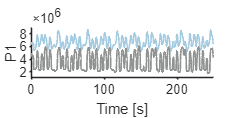

figure;
plot(data.t, data.Pa(:,1),'LineWidth',1,'color','#a5cbe0')
hold on 
plot(data.t, data.Pb(:,1),'LineWidth',1,'color','#919392')

set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim',[0, 250],'YLim',[1, 9]*1e6);
set(gcf,'unit','centimeters','position',[0 0 5 2.5]);
xlabel('Time [s]');ylabel('P1');
drawnow update;shg;
hold off

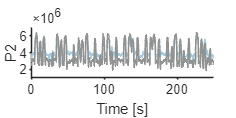

figure;
plot(data.t, data.Pa(:,2),'LineWidth',1,'color','#a5cbe0')
hold on 
plot(data.t, data.Pb(:,2),'LineWidth',1,'color','#919392')

set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim',[0, 250],'YLim',[1, 7]*1e6);
set(gcf,'unit','centimeters','position',[0 0 5 2.5]);
xlabel('Time [s]');ylabel('P2');
drawnow update;shg;
hold off

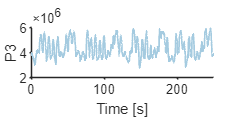

figure;
plot(data.t, data.Pa(:,3),'LineWidth',1,'color','#a5cbe0')
hold on 
plot(data.t, data.Pb(:,3),'LineWidth',1,'color','#919392')

set(gca, 'Box', 'off', 'TickDir', 'out', 'XLim',[0, 250]);
set(gcf,'unit','centimeters','position',[0 0 5 2.5]);
xlabel('Time [s]');ylabel('P3');
drawnow update;shg;
hold off

ans = 1.5001